Irene Celestino - Daniele Poidomani 

23/11/2021

# Logbook

## Es. 1

Correnti Laser, modello LDM 808 3LJ: 

- massima 25 mA - soglia a 19 mA ;

- tensione massima che gli dai: 6 V (da 3 V in poi);

- Potenza: 3 mW;

- Lunghezza d'onda: 808 nm.

Montiamo il circuito:

R1=150 Ohm (misura: 150.5 \pm 0.5 Ohm) : potenza massima dissipata è 150*(25 mA)^2 = 0.09 W e rimaniamo sotto 0.125 W, potenza massima della resistenza. Però usiamo quella da 0.5 W, per stare tranquilli. 

Manteniamo la tensione sotto 3 V per rimanere sotto i 20 mA (a 25 mA si avrebbe Vs=3,75, al massimo)

Messo il nero come catodo. 

Vmax = 6; % del laser
Pmax= 3e-3; % del laser
Imax = Pmax/Vmax % non torna

Imax =      5.000000000000000e-04


## Es. 2

Usiamo traccia V_I_DIFF per curva caratteristica corrente laser al variare di V: CB68-CB34

Spazzata:Vs tra 0.01 V e 3 V (così corrente massima è 20 mA)

Fondo scala: CB68 10 V  e CB34 5 V (è Vs, al max 3 V)

Prendiamo curva caratteristica con 50 misure 

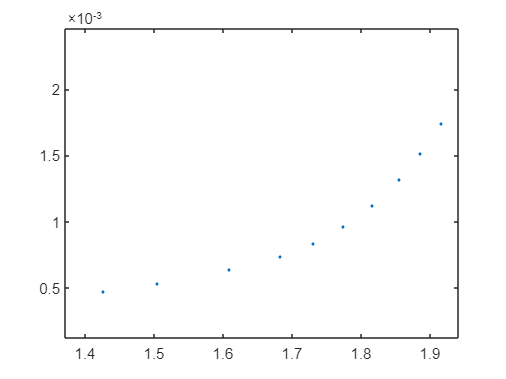

R=150;
dR=0.5;
datamat=readmatrix('Data LAB es 2 intorno a soglia');
V1=datamat(:,1);
V2=datamat(:,2);
V3=datamat(:,3);
V4=datamat(:,4);
I=V2/R;
plot(V1, I, '.')

## Es. 3

Riprendere le misure con più densità nella zona di Vt = 1.5/1.6 V.

h = 6.62607015e-34; %valore di CODATA atteso
e = 1.602176634e-19; %valore di CODATA atteso
c = 299792458;
Vt=1.55; %V
dVt=0.1; %V, presa ad occhio nel grafico, dove passa da lineare a emissione LED
E=e*Vt/c;
dE=e*dVt/c;
lambda=h/E

lambda =      7.998980544077438e-07


dlambda=h*dE/E^2

dlambda =      5.160632609082219e-08


## Es. 4

Scegliamo dimensioni circuito transimpedenza

Responsività = Corrente nel fotodiodo/potenza incidente = circa 0.45 a lambda 808 nm

potenza laser = 3 mW (massima) quindi corrente = 0.45*3mW viene 1.4 mA che scorre nel fotodiodo 

Vopamp=R*I quindi R=1 kOhm per avere Vopamp dell'ordine del V a potenza massima. Però non si arriva a potenza massima: mettiamo 10 kOhm 

Mettiamo fotodiodo con catodo (rosso) a terra, così corrente negativa (da -IN a terra)

## Es. 5

Testiamo cosa fa fotodiodo con illuminazione ambientale

Mettiamo 10 kOhm e luce ambientale segnale di frequenza 100 Hz ampio 30 mV picco picco e centrato in -40 mV (quindi corrente dell'ordine di 30 mV/ 10kOhm = circa uA 

Posizionando il fotodiodo nella postazione fissa, abbiamo come offset della luce ambientale nullo, con rumore di 0.005 V.

## Es. 6

Misura di CB33 (Vopamp) 

Mettiamo fotodiodo contro laser nel supporto e prendiamo curva Segnale Vopamp vs corrente nel laser. 

Impostazioni: 

- Vs tra 0.1 e 3 V 

- R = 150 Ohm 

- Fondo scala: CB68: 5 V e CB33: 0.5 V

Viene tipo una parabola 

IPD = Vopamp/Rtrans

Responsività = Corrente nel fotodiodo/potenza incidente

Potenza= IPD/Responsività = Vopamp /(Rtrans * responsività)

Vpeak=0.12; 
Rtrans= 10e3;
Resp=0.44; 
Pot_max=Vpeak/(Rtrans*Resp)

Pot_max =      2.727272727272727e-05


Abbiamo potenza massima di 27 uW

Decidiamo di alzare fino a 3.7 V Vin, per arrivare a correnti più vicine a 25 mA. Misura 'no fit' da 0.1 V a 3.7 V

Prendiamo misura con tanti punti per fare fit nella zona alta. Però OpAmp arriva fino a 23 mA e quindi ci fermiamo a Vs=3.45 V. 

Misura fit: da 2.7 V a 3.45 V in 100 misure 

Abbiamo scoperto il probkema: nel generatore corrente massima era impostata a 25 mA: lo alziamo a 30 mA

Nuova misura: fino a 3.7 V per arrivare a potenza massima (Vmax=1.7V) di 378 uW

Facciamo anche misura da 3.1 V a 3.75 V per il fit lineare. ('FIT FIT')

Pot_max=2.1/(Rtrans*Resp)

Pot_max =      6.818181818181819e-04


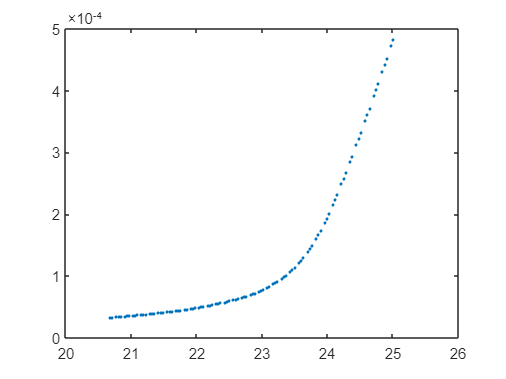

datamat=readmatrix('Data LAB es 6 quello buono');
Ilaser=datamat(:,1);
Vopamp=datamat(:,2);
Vopamp=Vopamp*(-1);

plot(Ilaser, Vopamp/(Rtrans*Resp), '.')

0.4/(Rtrans*Resp)

ans =      9.090909090909092e-05


I_100=3.4/150

I_100 =    0.022666666666667


## Es. 8 

Misura potenza con sensore: 

Vs=2.000 pm 0.001  15 uW

Vs=2.5  30 uW

Vs=3     50 uW 

Vs=3.5 138 uW 

Vs= 3.4 100 uW 

Vs=3.75 700 uW 

Vs= 4  viene ordine mW

Non sono compatibili con le nostre misure. Ne prendiamo un'altra mettendo a contatto laser e fotodiodo 

## Es. 9

Scegliamo potenza di 100 uW: 

Fattore tensione potenza: 

Potenza=  Vopamp /(Rtrans * responsività) cioè fattore = 228 uW/V 

1/(0.44*10e3)

ans =      2.272727272727273e-04


## Es. 11

Cuvette vuota

Riprendiamo misura senza cuvette con posizione laser per cui c'entra la cuvette  ("quello buono")

V = potenza*R*resp 

100e-6*10e3*0.45

ans =    0.450000000000000


A 100 uW serve tensione 0.45 V 

Nella nostra curva Vopamp 0.45 V a 23.4 mA pm 0.1 

Vs= 3.51 V

150*23.4e-3

ans =    3.510000000000000


dI=0.02/150

dI =      1.333333333333333e-04


Usiamo Vin_Vout2C.vi , impostiamo Vs a 3.5110 pm 0.0008 V

- senza cuvette: Vopamp = -0.440  pm 0.02 V (appena acceso, poi o sale o scende di anche 0.05) 

- con cuvette: (la mettiamo varie volte sempre più o meno in stessa posizione) 0.389 - 0.390 - 0.388 - 0.391 V - 0.389

- Errore per spostamento cuvette: 0.02 V

- Senza laser, col buio: -0.00158 pm 0.0003 V

Attenuazione_uW = (0.455-0.385)/(10e3*0.45)

Attenuazione_uW =      1.555555555555556e-05


## Es. 12

Concentrazioni: (misura con 0.5 V fs o 0.05 per le concentrazioni più alte)

1 : 0.01 M : Vopamp = 0.261 - 0.262 - 0.263 - 0.261 V

2: 0.05 M : Vopamp = 0.0683 - 0.0693 pm 0.0004 - 0.0699 - 00.6984

3: 0.1 M : Vopamp = 0.0316 - 0.0316 - 0.0317 

4. 0.25 M : (pm 0.0003)

5. 0.5 M:

6. 1 M :

V0=0.385;
dV0=0.02;
V1_array=[0.261  0.262  0.263  0.261];
V_op(1)=mean(V1_array)+0.0004;
dV_op(1)=std(V1_array)+0.0004;
V2_array=[ 0.0683  0.0693 0.0699  0.06984];
V_op(2)=mean(V2_array);
dV_op(2)=std(V2_array)+0.0004;
V3_array=[ 0.0316  0.0316  0.0317 ];
V_op(3)=mean(V3_array);
dV_op(3)=std(V3_array)+0.0004;
V4_array=[-0.0028];
dV_op(4)=0.0003;

V_op(4)=mean(V4_array);
V5_array=[-0.00303];
dV_op(5)=0.0003;
V_op(5)=mean(V5_array);
V6_array=[-0.00306];
V_op(6)=mean(V6_array);
dV_op(6)=0.0003;


c=[ 0.01, 0.05, 0.1, 0.25, 0.5, 1]; %M


I0=V0/(10e3*0.45)

I0 =      8.555555555555556e-05


I=V_op/(10e3*0.45);
dI=dV_op/(10e3*0.45);
V_op=V_op+0.0042;
plot(c, I,'.', 'MarkerSize',10)

pin=[I0, 10, 0];
modello=@(p,x)(p(1)*exp(-x*p(2))+p(3))

modello = function_handle with value:
    @(p,x)(p(1)*exp(-x*p(2))+p(3))


[p,resnorm,JJ,COVB,chi2n]=nlinfit(c, I, modello, pin, 'Weights', dI.^(-2));
p(1)

ans =      7.321678493176576e-05


p(2)

ans =   24.538982867824970


p(3)

ans =     -6.172775765364317e-07



for i=1:length(p)
    err_parametri(i)=sqrt(COVB(i,i));
end

chi2=chi2n

chi2 =      2.243139438709951e+02


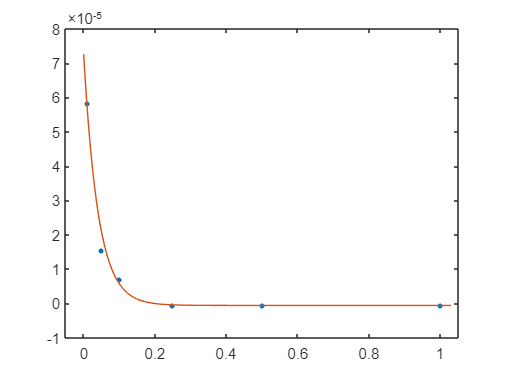


xx=linspace(0, 1.03, 1000);
yy=modello(p, xx);
hold on
plot(xx, yy)
hold off
xlim([-0.05, 1.05]);

Offset OpAmp del circuito con fotodiodo = 0.0042 +- 0.0003 V 

## Es. 17 -

Riprendiamo i dati per la potenza, Traccia_L_I, Vmin = 2.9 V, Vmax = 3.75 V, 100 misure con forndi scala entrambi 5 V e R = 150 +- 0.5 Ohm.

File chiamato "Data LAB es 6 fino a 3.2 V".

Vin = 3 V, da cui potenza ideale 50 mW.

V0=0.1145; %0.1149 0.1150
dV0=0.02;

V1_array=[0.0839  0.0855  0.0861  0.0856];
V_op(1)=mean(V1_array)+0.0004;
dV_op(1)=std(V1_array)+0.0004;

V2_array=[ 0.0251  0.0254 0.0253  0.0252];
V_op(2)=mean(V2_array);
dV_op(2)=std(V2_array)+0.0004;

V3_array=[ 0.0076  0.0076  0.0077 ];
V_op(3)=mean(V3_array);
dV_op(3)=std(V3_array)+0.0004;

V4_array=[-0.0027];
dV_op(4)=0.0003;
V_op(4)=mean(V4_array);

V5_array=[-0.0029];
dV_op(5)=0.0003;
V_op(5)=mean(V5_array);

V6_array=[-0.0030];
V_op(6)=mean(V6_array);
dV_op(6)=0.0003;


c=[0.01, 0.05, 0.1, 0.25, 0.5, 1]; %M


I0=V0/(10e3*0.45)

I0 =      2.544444444444445e-05


I=V_op/(10e3*0.45);
dI=dV_op/(10e3*0.45);
V_op=V_op+0.0039;
plot(c, I,'.', 'MarkerSize',10)

pin=[I0, 10, 0];
modello=@(p,x)(p(1)*exp(-x*p(2))+p(3))

modello = function_handle with value:
    @(p,x)(p(1)*exp(-x*p(2))+p(3))


[p,resnorm,JJ,COVB,chi2n]=nlinfit(c, I, modello, pin, 'Weights', dI.^(-2));
p(1)

ans =      2.489154767490641e-05


p(2)

ans =   26.415528869888846


p(3)

ans =     -6.088822051284439e-07



for i=1:length(p)
    err_parametri(i)=sqrt(COVB(i,i));
end
chi2=chi2n

chi2 =   14.890917441984877


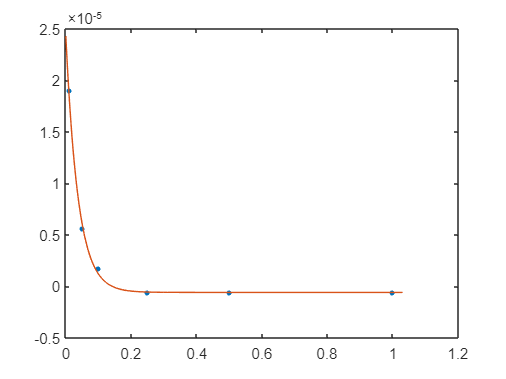


xx=linspace(0, 1.03, 1000);
yy=modello(p, xx);
hold on
plot(xx, yy)
hold off

Offset OpAmp del circuito con fotodiodo = 0.0039 +- 0.0003 V

Vin = 3.75 V, da cui potenza ideale 700 muW.

Pot_max=3.2/(Rtrans*Resp)

V0=2.68; %2.73 2.74

Imax =      1.000000000000000e-03


dV0=0.01;

V1_array=[1.872  1.863  1.862  1.866];
V_op(1)=mean(V1_array);
dV_op(1)=std(V1_array)+0.003;

V2_array=[ 0.585  0.583 0.581  0.587];
V_op(2)=mean(V2_array);
dV_op(2)=std(V2_array)+0.001;

V3_array=[ 0.215  0.216  0.219 0.218];
V_op(3)=mean(V3_array);
dV_op(3)=std(V3_array)+0.001;

V4_array=[-0.0024];
dV_op(4)=0.0003;
V_op(4)=mean(V4_array);

V5_array=[-0.00461];
dV_op(5)=0.00008;
V_op(5)=mean(V5_array);

V6_array=[-0.00465];
V_op(6)=mean(V6_array);
dV_op(6)=0.00008;


c=[0.01, 0.05, 0.1, 0.25, 0.5, 1]; %M


I0=V0/(10e3*0.45)
I=V_op/(10e3*0.45);
dI=dV_op/(10e3*0.45);
V_op=V_op+0.005;
plot(c, I,'.', 'MarkerSize',10)

pin=[I0, 10, 0];
modello=@(p,x)(p(1)*exp(-x*p(2))+p(3))
[p,resnorm,JJ,COVB,chi2n]=nlinfit(c, I, modello, pin, 'Weights', dI.^(-2));
p(1)
p(2)
p(3)

for i=1:length(p)
    err_parametri(i)=sqrt(COVB(i,i));
end
chi2=chi2n

xx=linspace(0, 1.03, 1000);
yy=modello(p, xx);
hold on
plot(xx, yy)
hold off

Offset OpAmp del circuito con fotodiodo = 0.005 +- 0.0003 V

# Laser 635 nm:

## Es. 1

Correnti Laser, modello LDM 808 3LJ: 

- massima 30 mA ;

- tensione massima che gli dai: 6 V (da 3 V in poi);

- Potenza: 3 mW;

- Lunghezza d'onda: 635 nm.

Montiamo il circuito:

R1=150 Ohm (misura: 150.5 \pm 0.5 Ohm) : potenza massima dissipata è 150*(30 mA)^2 = 0.135 W e non rimaniamo sotto 0.125 W, potenza massima della resistenza. Quindi usiamo quella da 0.5 W, per stare tranquilli. 

Manteniamo la tensione sotto 4.5 V per rimanere sotto i 20 mA (a 30 mA si avrebbe Vs=4.5, al massimo)

Messo il nero come catodo. 

Vmax = 3; % del laser
Pmax= 3e-3; % del laser
Imax = Pmax/Vmax % non torna

## Es. 2

Usiamo traccia V_I_DIFF per curva caratteristica corrente laser al variare di V: CB68-CB34

Spazzata:Vs tra 0.01 V e 4.5 V (così corrente massima è 30 mA)

Fondo scala: CB68 5 V  e CB34 10 V (è Vs, al max 4.5 V)

Prendiamo curva caratteristica con 100 misure 

R=150;

Pot_max =      1.150000000000000e-04


dR=0.5;
datamat=readmatrix('');
V1=datamat(:,1);
V2=datamat(:,2);
V3=datamat(:,3);

Pot_max =      5.250000000000001e-04


V4=datamat(:,4);
I=V2/R;

Error using readmatrix (line 158)
Unable to find or open ''. Check the path and filename or file permissions.

plot(V1, I, '.')

## Es. 3

Riprendere le misure con più densità nella zona di Vt = 1.5/1.6 V.

h = 6.62607015e-34; %valore di CODATA atteso
e = 1.602176634e-19; %valore di CODATA atteso
c = 299792458;
Vt=1.55; %V
dVt=0.1; %V, presa ad occhio nel grafico, dove passa da lineare a emissione LED
E=e*Vt/c;
dE=e*dVt/c;
lambda=h/E
dlambda=h*dE/E^2

## Es. 4

Scegliamo dimensioni circuito transimpedenza

Responsività = Corrente nel fotodiodo/potenza incidente = circa 0.4 a lambda 635 nm

potenza laser = 3 mW (massima) quindi corrente = 0.4*3mW viene 1.2 mA che scorre nel fotodiodo 

Vopamp=R*I quindi R=1 kOhm per avere Vopamp dell'ordine del V a potenza massima. Però non si arriva a potenza massima: mettiamo 10 kOhm 

Mettiamo fotodiodo con catodo (rosso) a terra, così corrente negativa (da -IN a terra)

## Es. 5

Testiamo cosa fa fotodiodo con illuminazione ambientale

Mettiamo 10 kOhm e luce ambientale segnale di frequenza 100 Hz ampio 30 mV picco picco e centrato in -40 mV (quindi corrente dell'ordine di 30 mV/ 10kOhm = circa uA 

Posizionando il fotodiodo nella postazione fissa, abbiamo come offset della luce ambientale nullo, con rumore di 0.005 V.

## Es. 6

Misura di CB33 (Vopamp) 

Mettiamo fotodiodo contro laser nel supporto e prendiamo curva Segnale Vopamp vs corrente nel laser. 

Impostazioni: 

- Vs tra 0.1 e 4.5 V 

- R = 150 Ohm 

- Fondo scala: CB68: 5 V e CB33: 5 V

- 100 misure

Viene tipo una parabola 

IPD = Vopamp/Rtrans

Responsività = Corrente nel fotodiodo/potenza incidente

Potenza= IPD/Responsività = Vopamp /(Rtrans * responsività)

Vpeak=0.46; 

ans =      2.500000000000000e-04


Rtrans= 10e3;
Resp=0.4; 
Pot_max=Vpeak/(Rtrans*Resp)

Abbiamo potenza massima di 115 uW

Facciamo anche misura da 4.2 V a 4.5 V per il fit lineare. (non va bene perchè andiamo oltre 4.2 V)

Pot_max=2.1/(Rtrans*Resp)

ans =    0.400000000000000


datamat=readmatrix('');
Ilaser=datamat(:,1);
Vopamp=datamat(:,2);
Vopamp=Vopamp*(-1);

plot(Ilaser, Vopamp/(Rtrans*Resp), '.')

## Es. 8 

Misura potenza con sensore: 

Vs=3    12  uW 

Vs=3.5 18 uW 

Vs= 4 39 uW 

Vs=4.2 145 uW 

Vs=4.5 184 uW

Non sono compatibili con le nostre misure. Ne prendiamo un'altra mettendo a contatto laser e fotodiodo 

## Es. 9

Scegliamo potenza di 145 uW: 

Fattore tensione potenza: 

Potenza=  Vopamp /(Rtrans * responsività) cioè fattore = 250 uW/V 

1/(0.4*10e3)

## Es. 11

Cuvette vuota

Riprendiamo misura senza cuvette con posizione laser per cui c'entra la cuvette  ("quello buono")

V = potenza*R*resp 

100e-6*10e3*0.4

Vs= 4.2 V

Usiamo Vin_Vout2C.vi , impostiamo Vs a 4.201 pm 0.001 V

- senza cuvette: Vopamp = 0.43  pm 0.02 V (appena acceso, poi o sale o scende di anche 0.05) 

- con cuvette: (la mettiamo varie volte sempre più o meno in stessa posizione) 0.323, 0.318.

- Errore per spostamento cuvette: 0.02 V

- Senza laser, col buio: Vopamp = 0.0016  pm 0.0003 V

## Es. 12

Concentrazioni: (misura con 0.5 V fs o 0.05 per le concentrazioni più alte)

1 : 0.01 M

2: 0.05 M

3: 0.1 M

4. 0.25 M

5. 0.5 M:

6. 1 M :

V0=0.320;
dV0=0.02;

V1_array=[0.294];
V_op(1)=mean(V1_array);
dV_op(1)=0.005;

V2_array=[0.245];
V_op(2)=mean(V2_array);
dV_op(2)=0.005;

V3_array=[0.224];
V_op(3)=mean(V3_array);
dV_op(3)=0.005;

V4_array=[0.107];
dV_op(4)=0.005;
V_op(4)=mean(V4_array);

V5_array=[0.031];
dV_op(5)=0.003;
V_op(5)=mean(V5_array);

V6_array=[-0.0032];
V_op(6)=mean(V6_array);
dV_op(6)=0.0005;


c=[0.01, 0.05, 0.1, 0.25, 0.5, 1]; %M

I0 =      8.000000000000001e-05




I0=V0/(10e3*0.4)
I=V_op/(10e3*0.4);
dI=dV_op/(10e3*0.4);
V_op=V_op+0.0073;
plot(c, I,'.', 'MarkerSize',10)

modello = function_handle with value:
    @(p,x)(p(1)*exp(-x*p(2))+p(3))



pin=[I0, 10, 0];

ans =      7.986095621675030e-05


modello=@(p,x)(p(1)*exp(-x*p(2))+p(3))

ans =    3.948463844659482


[p,resnorm,JJ,COVB,chi2n]=nlinfit(c, I, modello, pin, 'Weights', dI.^(-2));

ans =     -2.357007514629696e-06


p(1)
p(2)
p(3)

for i=1:length(p)
    err_parametri(i)=sqrt(COVB(i,i));

chi2 =    6.068181794538553


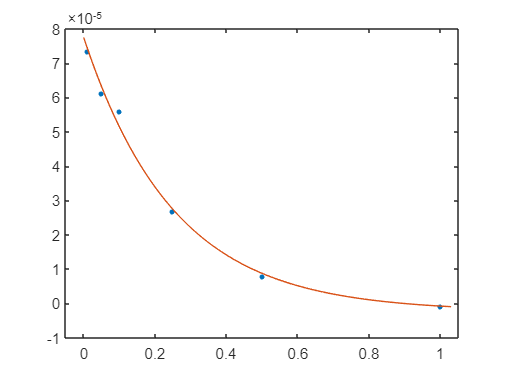

end

chi2=chi2n

xx=linspace(0, 1.03, 1000);
yy=modello(p, xx);
hold on

plot(xx, yy)
hold off
xlim([-0.05, 1.05]);

Offset OpAmp del circuito con fotodiodo = 0.0073 +- 0.0003 V 